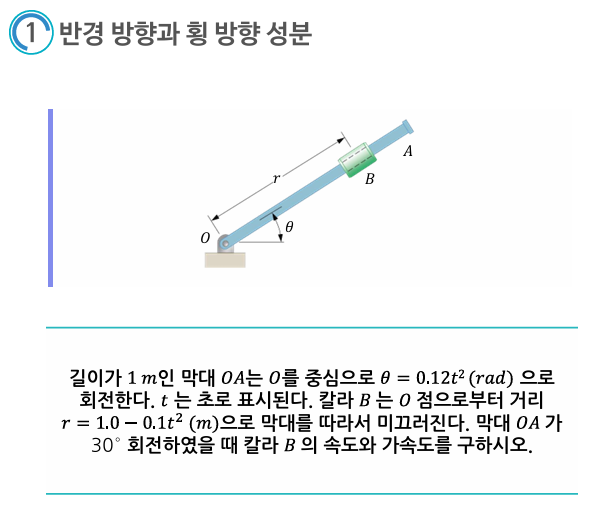

**문제 요약**

- 막대 $OA$의 길이는 $1 \, \text{m}$

- 각도 $\theta = 0.12t^2$ (rad), $t$는 초

- $r = 1.0 - 0.1t^2(m)$, 칼라 $B$의 거리

- $\theta = 30^\circ$에서 칼라 $B$의 속도와 가속도를 구하라.

**1. 각도 및 시간 관계**

- 각도 $\theta$는 $0.2t^2$로 주어졌습니다.

- 반지름 $ r$은 $1.0 - 0.1t^2$입니다.

**2. 각속도와 각가속도**

- 각속도 $\omega = \frac{d\theta}{dt}$:


$$\theta = 0.2t^2 $$



$$\omega = \frac{d\theta}{dt} = 0.4t$$


- 각가속도 

$\alpha = \frac{d\omega}{dt}$�:


$$\alpha = 0.4$$


3**. 칼라 **$B$**의 속도와 가속도**

- 칼라$ B$의 위치 $r = 1.0 - 0.1t^2$:


$$\frac{dr}{dt} = \frac{d}{dt}(1.0 - 0.1t^2) = -0.2t$$


- 칼라$ B$의 속도 $v_B$�:


$$v_B = \sqrt{\left(\frac{dr}{dt}\right)^2 + (r\omega)^2}$$


$v_B = \sqrt{(-0.2t)^2 + \left[(1.0 - 0.1t^2) \times 0.4t\right]^2}$�

- 칼라 $B$의 가속도 $a_B$�:

- 가속도에는 두 가지 성분이 있습니다: 접선 가속도와 반경 방향 가속도.


$$a_r = \frac{d^2r}{dt^2} - r\omega^2$$



$$a_r = -0.2 - (1.0 - 0.1t^2) \times (0.4t)^2$$



$$a_{\theta} = r\alpha + 2\frac{dr}{dt}\omega$$



$$a_{\theta} = (1.0 - 0.1t^2) \times 0.4 + 2 \times (-0.2t) \times 0.4t   $$


**4. **$\theta = 30^\circ$**일 때 시간 구하기**

- $\theta = 30^\circ = \frac{\pi}{6} rad$일 때:


$$0.2t^2 = \frac{\pi}{6}  $$



$$t^2 = \frac{\pi}{1.2} = \frac{5\pi}{6 $$


$t = \sqrt{\frac{5\pi}{6}}$��

% 상수 정의
theta_deg = 30; % 각도 (도 단위)
theta_rad = deg2rad(theta_deg); % 각도 (라디안 단위)

% theta와 r의 함수
theta_coeff = 0.2;
r_coeff = 0.1;

% 시간 계산
t = sqrt(theta_rad / theta_coeff);

% 각속도와 각가속도
omega = 2 * theta_coeff * t;
alpha = 2 * theta_coeff;

% 칼라 B의 위치와 속도
r = 1.0 - r_coeff * t^2;
dr_dt = -2 * r_coeff * t;

% 칼라 B의 속도
v_B = sqrt((dr_dt)^2 + (r * omega)^2);

% 가속도 계산
d2r_dt2 = -2 * r_coeff;
a_r = d2r_dt2 - r * omega^2;
a_theta = r * alpha + 2 * dr_dt * omega;

% 총 가속도
a_B = sqrt(a_r^2 + a_theta^2);

% 결과 출력
fprintf('칼라 B의 속도 v_B: %.4f m/s\n', v_B);

칼라 B의 속도 v_B: 0.5770 m/s


fprintf('칼라 B의 가속도 a_B: %.4f m/s^2\n', a_B);

칼라 B의 가속도 a_B: 0.5240 m/s^2


칼라 B의 속도 v_B: 0.5770 m/s


칼라 B의 가속도 a_B: 0.5240 m/s^2


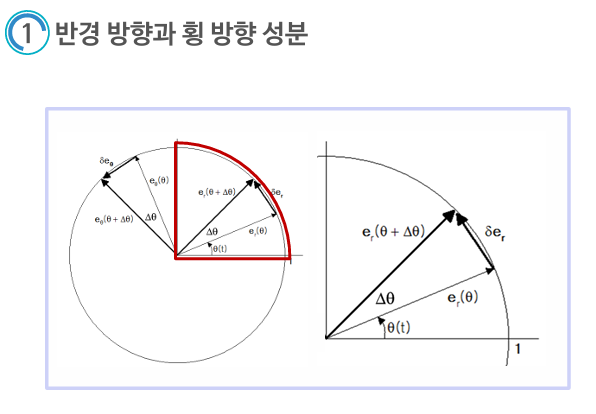

**반경 방향 및 회전 방향 성분**

- **반경 방향 (**$e_r$**�****)**:

- 물체의 운동 방향이 중심을 향하는 방향입니다.

- 속도와 가속도의 성분 중 원의 중심을 향하는 부분입니다.

- **회전 방향 (**$e_\theta$**�****)**:

- 물체의 운동 방향이 원의 접선 방향을 따라가는 방향입니다.

- 물체의 각속도에 의한 속도 성분이 해당됩니다.

**속도와 가속도 성분의 분석**

회전 운동에서는 물체의 위치를 극좌표로 표현할 때 속도와 가속도의 두 가지 성분으로 나눌 수 있습니다.

**속도 (**$v$**)**

속도는 반경 방향과 회전 방향의 두 가지 성분으로 나뉩니다:

$v = \frac{d\mathbf{r}}{dt} = \frac{dr}{dt}e_r + r\frac{d\theta}{dt}e_\theta$�

- $\frac{dr}{dt}$�: 반경 방향의 변화율 (축방향 속도 성분)

- $\frac{d\theta}{dt}$�: 회전 방향의 속도 성분 (각속도 $\omega$로 인한 접선 속도)

**가속도 (**$a$**)**

가속도도 마찬가지로 두 성분으로 나뉩니다:

$a = \left( \frac{d^2r}{dt^2} - r\left(\frac{d\theta}{dt}\right)^2 \right)e_r + \left( r\frac{d^2\theta}{dt^2} + 2\frac{dr}{dt}\frac{d\theta}{dt} \right)e_\theta$�

- 반경 방향 가속도 ($e_r$ 성분):


$$a_r = \frac{d^2r}{dt^2} - r\left(\frac{d\theta}{dt}\right)^2$$


- $\frac{d^2r}{dt^2}$�: 반경 방향의 가속도 성분

- $r\left(\frac{d\theta}{dt}\right)^2$: 원심 가속도 성분 (반경 방향 가속도의 일부)

- 회전 방향 가속도 ($e_\theta$� 성분):

$a_\theta = r\frac{d^2\theta}{dt^2} + 2\frac{dr}{dt}\frac{d\theta}{dt}$�

- $r\frac{d^2\theta}{dt^2}$: 각가속도에 의한 가속도 성분

- $2\frac{dr}{dt}\frac{d\theta}{dt}$�: 코리올리 가속도 성분

**예시 적용**

주어진 조건을 사용하여 구체적으로 적용할 수 있습니다.


$$\theta = 0.2t^2, \quad r = 1.0 - 0.1t^2$$


- **각속도 (**$\omega$**)**:


$$\omega = \frac{d\theta}{dt} = 0.4t$$


- **각가속도 (**$\alpha$**)**:


$$\alpha = \frac{d\omega}{dt} = 0.4$$


- **반경 방향 속도 및 가속도**:


$$\frac{dr}{dt} = -0.2t, \quad \frac{d^2r}{dt^2} = -0.2$$


- **가속도 성분**:

- 반경 방향 가속도:


$$a_r = -0.2 - (1.0 - 0.1t^2)(0.4t)^2$$


- 회전 방향 가속도:


$$a_\theta = (1.0 - 0.1t^2) \times 0.4 + 2 \times (-0.2t) \times 0.4t$$


% 상수 및 초기 조건
theta_deg = 30; % 각도 (degree)
theta_rad = deg2rad(theta_deg); % 각도 (radian)

% 주어진 수식의 계수
theta_coeff = 0.2;
r_coeff = 0.1;

% 시간 계산
t = sqrt(theta_rad / theta_coeff);

% 각속도와 각가속도 계산
omega = 2 * theta_coeff * t; % d(theta)/dt = 0.4 * t
alpha = 2 * theta_coeff; % d^2(theta)/dt^2 = 0.4

% 반지름 r 및 그에 대한 시간에 따른 변화율
r = 1.0 - r_coeff * t^2; % r = 1.0 - 0.1 * t^2
dr_dt = -2 * r_coeff * t; % dr/dt = -0.2 * t
d2r_dt2 = -2 * r_coeff; % d^2r/dt^2 = -0.2

% 반경 방향 가속도 (a_r)
a_r = d2r_dt2 - r * omega^2;

% 회전 방향 가속도 (a_theta)
a_theta = r * alpha + 2 * dr_dt * omega;

% 칼라 B의 속도 (v_B) 및 가속도 (a_B) 계산
v_B = sqrt((dr_dt)^2 + (r * omega)^2); % 속도
a_B = sqrt(a_r^2 + a_theta^2); % 총 가속도

% 결과 출력
fprintf('칼라 B의 속도 v_B: %.4f m/s\n', v_B);

칼라 B의 속도 v_B: 0.5770 m/s


fprintf('칼라 B의 가속도 a_B: %.4f m/s^2\n', a_B);

칼라 B의 가속도 a_B: 0.5240 m/s^2


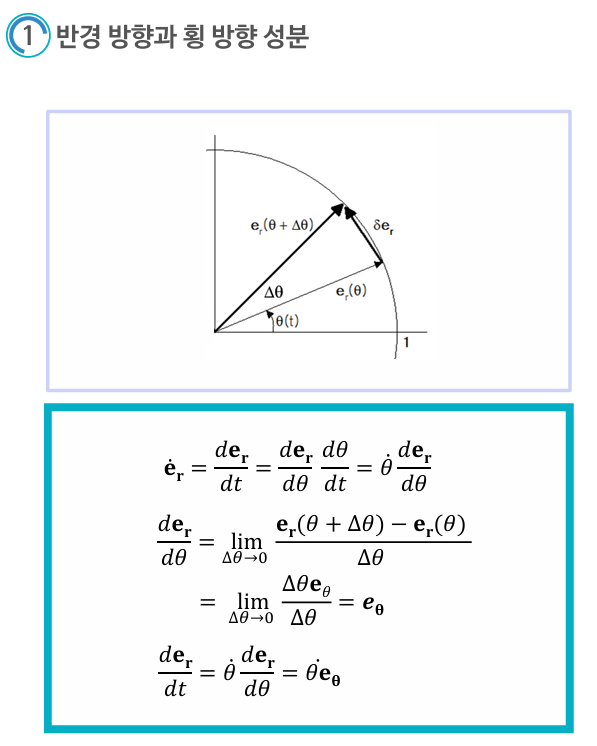

**수식 유도 과정**

- **반경 방향 단위 벡터 **$e_r$**의 변화**:

- $e_r$는 반경 방향을 나타내는 단위 벡터로, 원운동에서 각도$\theta$에 따라 방향이 변화합니다.

- $\theta$가 증가하면 $e_r$�의 방향도 변하는데, 이 변화를 $\Delta \theta$만큼의 각도 변화로 표현할 수 있습니다.

- **변화율 계산**:

- 각도 $\theta$가 $\Delta \theta$만큼 변화할 때 $e_r$의 변화는 다음과 같이 나타낼 수 있습니다:

$\frac{de_r}{d\theta} = \lim_{\Delta\theta \to 0} \frac{e_r(\theta + \Delta\theta) - e_r(\theta)}{\Delta\theta}$�

- **벡터의 변화**:

- $e_r(\theta)$에서 $e_r(\theta + \Delta\theta)$로 변할 때, 그 벡터의 변화는 $\Delta \theta$에 비례하며, 이 변화는 회전 방향 벡터 $e_\theta$와 관련이 있습니다.

- $e_r(\theta + \Delta\theta) - e_r(\theta)$는 $\Delta \theta$만큼의 회전 방향 성분으로 바뀝니다.

- 이 변화는 실제로 $\Delta\theta$에 비례하며, 그 비례 상수는 $e_\theta$�입니다.

- **극한을 통한 미분**:

- 이 변화를 극한으로 나타내면:

$\frac{de_r}{d\theta} = \lim_{\Delta\theta \to 0} \frac{\Delta\theta e_\theta}{\Delta\theta} = e_\theta$�

- **최종 결과**:

- 결과적으로, 반경 방향 단위 벡터 $e_r$�의 각도 $\theta$에 대한 미분은 회전 방향 단위 벡터 $e_\theta$와 같습니다:

$\frac{de_r}{d\theta} = e_\theta$�

**해석**

- 이 결과는 반경 방향 단위 벡터 $e_r$가 각도 $\theta$에 따라 변화할 때 그 변화 방향이 항상 회전 방향 단위 벡터 $e_\theta$�를 향한다는 것을 보여줍니다.

- 즉, $e_r$�의 변화는 단순히 크기만 변하는 것이 아니라, 방향의 변화로 나타나며, 이 방향의 변화가 바로 $e_\theta$�의 방향과 일치함을 의미합니다.

**반경 방향 및 회전 방향 성분**

- **반경 방향 단위 벡터 (**$e_r$**)의 시간에 따른 변화**:

- 반경 방향 단위 벡터 $e_r$�는 원의 중심을 향하는 방향을 나타내며, 원운동의 경우 시간에 따라 방향이 변합니다.

- $e_r$�의 시간에 따른 변화율은 다음과 같이 나타낼 수 있습니다:

$\dot{e_r} = \frac{de_r}{dt}$��

- **회전 방향 단위 벡터 (**$e_\theta$**�****)의 정의**:

- 회전 방향 단위 벡터 $e_\theta$는 반경 방향에 대해 수직인 방향을 나타내며, 원의 접선 방향을 따라갑니다.

- $e_\theta$의 변화는 원운동의 각속도에 직접적으로 영향을 받습니다.

**수식 유도**

- 반경 방향 단위 벡터의 시간 변화는 각속도 $˙\dot{\theta}$˙에 따라 회전 방향 단위 벡터 $e_\theta$�로 변환됩니다.

- 이 관계는 다음과 같이 유도됩니다:

$\dot{e_r} = \frac{de_r}{dt} = \frac{de_r}{d\theta} \cdot \frac{d\theta}{dt} = \dot{\theta} \frac{de_r}{d\theta}$��

- 단위 벡터 $e_r$의 각도에 대한 변화율은:

$\frac{de_r}{d\theta} = e_\theta$�

따라서,

$\dot{e_r} = \dot{\theta} e_\theta$�

**해석**

- 위의 수식은 반경 방향 단위 벡터 $e_r$�가 시간에 따라 변화할 때, 그 변화가 회전 방향 단위 벡터 $e_\theta$에 비례함을 보여줍니다.

- 각속도$˙\dot{\theta}$˙가 빠를수록 $e_r$의 변화율도 커집니다.

- 이 수식을 통해 원운동을 하는 물체의 가속도를 분석할 때 반경 방향과 회전 방향의 가속도 성분을 구분할 수 있습니다.

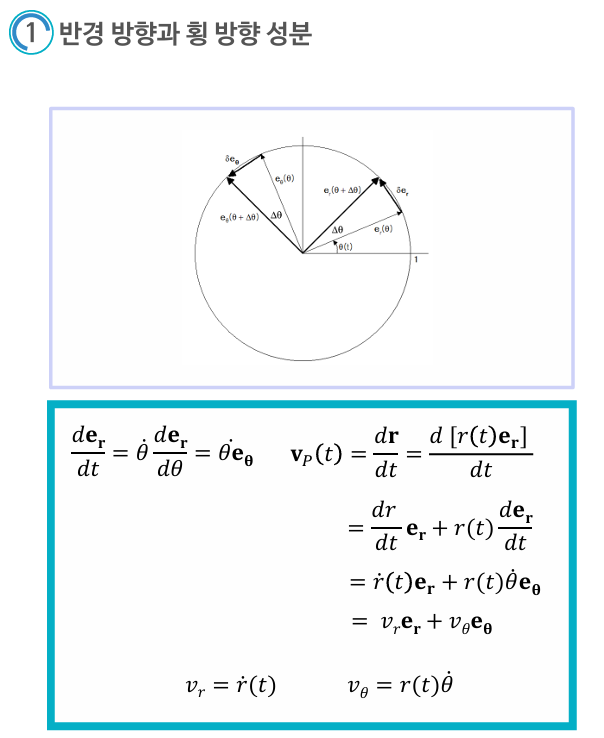

**1. 단위 벡터의 변화**

- 반경 방향 단위 벡터 $e_r$와 회전 방향 단위 벡터 $e_\theta$�는 각도$\theta$에 따라 변합니다.

- $e_r$의 변화율은 다음과 같습니다:

$\frac{de_r}{dt} = \dot{\theta} \frac{de_r}{d\theta} = \dot{\theta} e_\theta$�

이는 $e_r$의 시간에 대한 변화가 회전 방향 단위 벡터 $e_\theta$와 관련됨을 나타냅니다.

**2. 속도 벡터 **$\mathbf{v_p}(t)$

- 물체의 위치 벡터 $\mathbf{r}(t) = r(t) e_r$입니다.

- 위치 벡터를 미분하여 속도를 구합니다:


$$\mathbf{v_p}(t) = \frac{d\mathbf{r}}{dt} = \frac{d}{dt} [r(t) e_r]$$


- 곱의 미분 법칙을 사용하여 전개하면:

$\mathbf{v_p}(t) = \frac{dr}{dt} e_r + r(t) \frac{de_r}{dt}$��

- 이미 구한 $\frac{de_r}{dt} = \dot{\theta} e_\theta$를 대입하면:

$\mathbf{v_p}(t) = \dot{r} e_r + r(t) \dot{\theta} e_\theta$�

여기서:

- $\dot{r} = \frac{dr}{dt}$�는 반경 방향 속도 성분입니다.

- $r(t) \dot{\theta}$는 회전 방향 속도 성분입니다.

**3. 속도의 두 성분**

속도 벡터는 반경 방향 성분과 회전 방향 성분으로 나뉩니다:

- 반경 방향 속도 ($v_r$�):


$$v_r = \dot{r}(t)$$


- 회전 방향 속도 ($v_\theta$):


$$v_\theta = r(t) \dot{\theta}$$


따라서, 속도 벡터를 다음과 같이 표현할 수 있습니다:


$$\mathbf{v_p}(t) = v_r e_r + v_\theta e_\theta$$


% 각도와 반경에 대한 시간 함수
theta = @(t) 0.2 * t.^2; % 각도
r = @(t) 1.0 - 0.1 * t.^2; % 반경

% 시간에서 각속도와 각가속도
omega = @(t) 0.4 * t; % 각속도 d(theta)/dt
alpha = 0.4; % 각가속도 d^2(theta)/dt^2

% 속도 성분 계산
t_value = 2; % 예시로 t = 2에서 계산
vr = @(t) -0.2 * t; % 반경 방향 속도
vtheta = @(t) r(t) .* omega(t); % 회전 방향 속도

% 속도 계산
vr_value = vr(t_value);
vtheta_value = vtheta(t_value);

fprintf('t = %.2f일 때 반경 방향 속도 v_r: %.4f m/s\n', t_value, vr_value);

t = 2.00일 때 반경 방향 속도 v_r: -0.4000 m/s


fprintf('t = %.2f일 때 회전 방향 속도 v_theta: %.4f m/s\n', t_value, vtheta_value);

t = 2.00일 때 회전 방향 속도 v_theta: 0.4800 m/s


**위치 벡터 **$r(t)$

- 물체의 위치를 극좌표계로 표현할 때, 위치 벡터$r(t)$는 다음과 같이 표현됩니다: $\mathbf{r}(t) = r(t) e_r$� 

여기서:

- $r(t)$: 시간 $t$에 따른 반경 (크기)

- $e_r$: 반경 방향 단위 벡터

**속도 벡터 **$\mathbf{v_p}(t)$** 유도**

- 속도는 위치 벡터를 시간에 대해 미분하여 얻습니다:$\mathbf{v_p}(t) = \frac{d\mathbf{r}(t)}{dt}$이를 $\mathbf{r}(t) = r(t) e_r$�에 대입하면:


$$\mathbf{v_p}(t) = \frac{d}{dt} [r(t) e_r]$$


**곱의 미분 법칙 적용**

- $r(t) e_r$�는 두 함수$r(t)$와 $e_r$의 곱이므로, 곱의 미분 법칙을 적용합니다:

$\mathbf{v_p}(t) = \frac{dr(t)}{dt} e_r + r(t) \frac{de_r}{dt}$��

여기서:

- $\frac{dr(t)}{dt}$: 반경 $r(t)$의 시간에 따른 변화율

- $\frac{de_r}{dt}$: 단위 벡터 $e_r$의 시간에 따른 변화율

**단위 벡터 **ere_r**e****r****�****의 변화율**

- 앞서 언급한 바와 같이, 단위 벡터 $e_r$는 각도 $\theta$에 따라 방향이 변하기 때문에 시간에 따른 변화율은 회전 방향 단위 벡터 $e_\theta$�와 각속도 $\dot{\theta}$에 의해 결정됩니다: 

$\frac{de_r}{dt} = \dot{\theta} e_\theta$�

**최종 속도 벡터 식**

- 이제 이 결과를 속도 벡터 식에 대입하면:

$\mathbf{v_p}(t) = \frac{dr(t)}{dt} e_r + r(t) \dot{\theta} e_\theta$�

이를 간단히 나타내면:

$\mathbf{v_p}(t) = \dot{r} e_r + r\dot{\theta} e_\theta$�

여기서:

- $\dot{r} = \frac{dr(t)}{dt}$�: 반경 방향 속도

- $r\dot{\theta}$: 회전 방향 속도

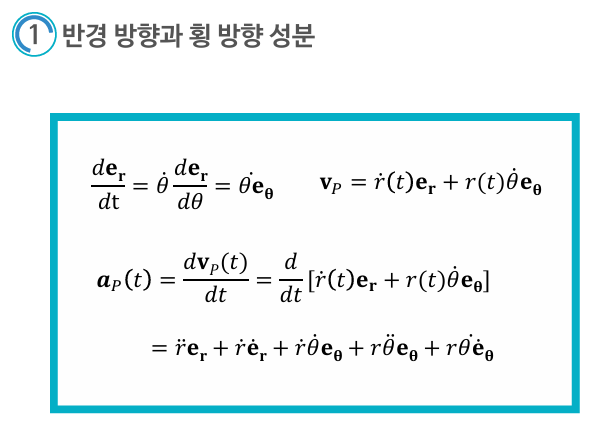

**1. 속도 벡터 **$\mathbf{v_p}(t)$

- 물체의 속도 벡터는 다음과 같이 표현됩니다: 

$\mathbf{v_p}(t) = \dot{r}(t) e_r + r(t) \dot{\theta} e_\theta$�

여기서:

- $\dot{r}(t)$: 반경 방향 속도

- $\dot{\theta}$: 각속도

- $e_r$�: 반경 방향 단위 벡터

- $e_\theta$�: 회전 방향 단위 벡터

**2. 속도 벡터의 미분**

- 가속도 벡터 $\mathbf{a_p}(t)$를 얻기 위해 속도 벡터$\mathbf{v_p}(t)$를 시간에 대해 미분합니다: 


$$\mathbf{a_p}(t) = \frac{d\mathbf{v_p}(t)}{dt} = \frac{d}{dt}[\dot{r}(t) e_r + r(t) \dot{\theta} e_\theta]$$


**3. 미분 과정**

- 곱의 미분 법칙을 적용하여 각 항을 미분합니다:

- $\dot{r}(t) e_r$의 미분:

$\frac{d}{dt}[\dot{r}(t) e_r] = \ddot{r}(t) e_r + \dot{r}(t) \frac{de_r}{dt}$��

- $\ddot{r}(t)$: 반경 방향 가속도

- $\frac{de_r}{dt} = \dot{\theta} e_\theta$�이므로,

$\frac{d}{dt}[\dot{r}(t) e_r] = \ddot{r}(t) e_r + \dot{r}(t) \dot{\theta} e_\theta$�

- $r(t) \dot{\theta} e_\theta$�의 미분:

$\frac{d}{dt}[r(t) \dot{\theta} e_\theta] = \frac{dr(t)}{dt} \dot{\theta} e_\theta + r(t) \ddot{\theta} e_\theta + r(t) \dot{\theta} \frac{de_\theta}{dt}$��

- $\frac{de_\theta}{dt} = -\dot{\theta} e_r$이므로,

$\frac{d}{dt}[r(t) \dot{\theta} e_\theta] = \dot{r}(t) \dot{\theta} e_\theta + r(t) \ddot{\theta} e_\theta - r(t) \dot{\theta}^2 e_r$�

**4. 가속도 벡터의 최종 표현**

- 위의 두 항을 모두 합치면 가속도 벡터 $\mathbf{a_p}(t)$를 얻을 수 있습니다: 


$$\mathbf{a_p}(t) = \ddot{r}(t) e_r + \dot{r}(t) \dot{\theta} e_\theta + \dot{r}(t) \dot{\theta} e_\theta + r(t) \ddot{\theta} e_\theta - r(t) \dot{\theta}^2 e_r$$


�정리하면, 

$\mathbf{a_p}(t) = (\ddot{r}(t) - r(t) \dot{\theta}^2) e_r + (r(t) \ddot{\theta} + 2\dot{r}(t) \dot{\theta}) e_\theta$�

**5. 결론**

- 이 결과는 원운동을 하는 물체의 가속도를 반경 방향과 회전 방향으로 분해하여 나타냅니다.

- 반경 방향 가속도: 


$$a_r = \ddot{r}(t) - r(t) \dot{\theta}^2$$


- 이는 중심에서 바깥쪽으로 향하는 가속도를 나타냅니다.

- 회전 방향 가속도: 


$$a_\theta = r(t) \ddot{\theta} + 2\dot{r}(t) \dot{\theta}$$


- 이는 접선 방향으로의 가속도를 나타냅니다.

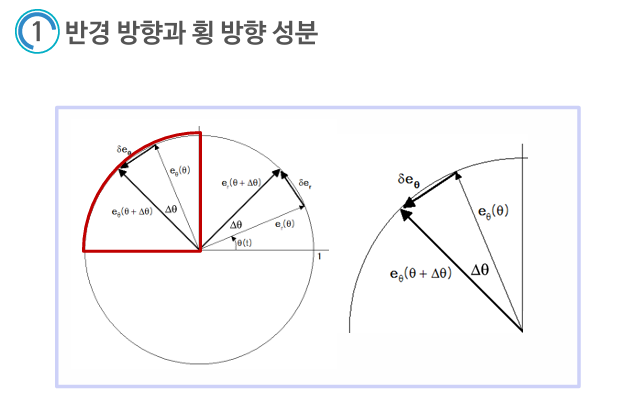

**단위 벡터의 변화**

- **반경 방향 단위 벡터 (**$e_r$**)**:

- 원의 중심을 향하는 방향을 나타내는 벡터입니다.

- 각도 $\theta$에 따라 방향이 변합니다.

- 그림에서 $e_r(\theta)$가$e_r(\theta + \Delta\theta)$로 변하는 것을 볼 수 있습니다.

- 이 변화는 각도 $\Delta\theta$에 의해 발생하며, 회전 방향 벡터 $e_\theta$�로 변환됩니다.

- **회전 방향 단위 벡터 (**$e_\theta$**�****)**:

- 원의 접선 방향을 나타내는 벡터입니다.

- $e_r$의 방향 변화에 따라 $e_\theta$도 함께 변합니다.

- $e_\theta(\theta)$에서$e_\theta(\theta + \Delta\theta)$로 변화하는 모습이 그림에 나타나 있습니다.

**수식 유도**

그림을 통해 단위 벡터의 변화율을 유도할 수 있습니다:

- **반경 방향 단위 벡터의 변화**:

- $e_r$�의 각도에 대한 변화율은:

$\frac{de_r}{d\theta} = e_\theta$�

- 이는 각도$\theta$가 $\Delta\theta$만큼 변할 때 $e_r$의 변화가 $e_\theta$� 방향으로 발생함을 의미합니다.

- 따라서, 시간에 대한 변화율은:

$\frac{de_r}{dt} = \dot{\theta} e_\theta$�

- **회전 방향 단위 벡터의 변화**:

- 마찬가지로 $e_\theta$�의 각도에 대한 변화율은:

$\frac{de_\theta}{d\theta} = -e_r$�

- 시간에 대한 변화율은:

$\frac{de_\theta}{dt} = \dot{\theta} (-e_r) = -\dot{\theta} e_r$�

**해석**

- $e_r$와 $e_\theta$�의 변화는 각속도 $\dot{\theta}$에 직접적으로 의존하며, 서로 수직인 두 벡터가 원운동을 하는 동안 어떻게 변화하는지를 보여줍니다.

- 반경 방향 단위 벡터 $e_r$�는 회전 방향 단위 벡터 $e_\theta$의 방향으로 변화하며, 이 변화는 각속도에 의해 결정됩니다.

- 회전 방향 단위 벡터 $e_\theta$는 반경 방향 단위 벡터 $e_r$�의 반대 방향으로 변화합니다.

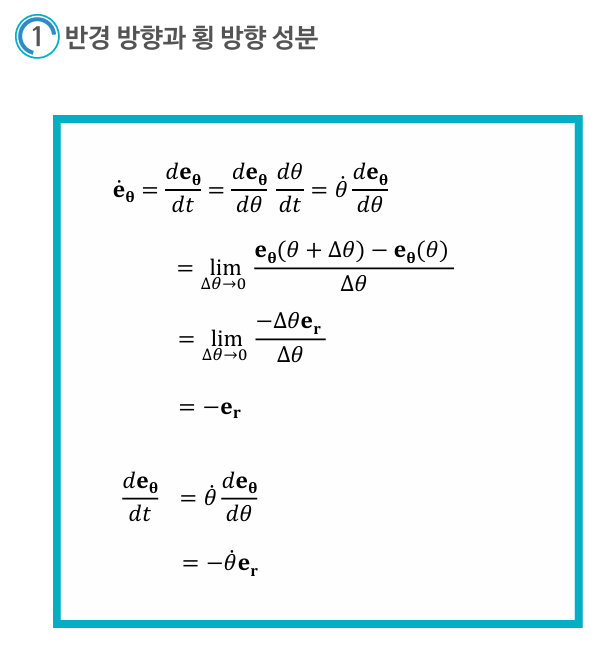

**회전 방향 단위 벡터의 변화**

- **회전 방향 단위 벡터의 미분**:

- 회전 방향 단위 벡터 $e_\theta$의 시간에 따른 변화율을 구하기 위해 $e_\theta$�를 시간에 대해 미분합니다.

$\dot{e_\theta} = \frac{de_\theta}{dt}$��

- **각도에 대한 미분**:

- $e_\theta$를 각도 $\theta$에 대해 미분한 후, $\theta$를 시간에 대해 미분합니다:

$\dot{e_\theta} = \frac{de_\theta}{d\theta} \frac{d\theta}{dt} = \dot{\theta} \frac{de_\theta}{d\theta}$��

- 여기서 $\dot{\theta}$는 각속도입니다.

- **미분의 정의**:

- 단위 벡터$e_\theta$의 각도에 대한 변화율을 정의합니다:

$\frac{de_\theta}{d\theta} = \lim_{\Delta\theta \to 0} \frac{e_\theta(\theta + \Delta\theta) - e_\theta(\theta)}{\Delta\theta}$�

- **변화의 방향**:

- 그림에 따르면, $e_\theta$가 $\Delta\theta$만큼 변할 때, 이 변화는 반경 방향 벡터 $e_r$와 관련이 있습니다.

- 변화량은 $-\Delta\theta e_r$로 나타납니다.

$\frac{de_\theta}{d\theta} = \lim_{\Delta\theta \to 0} \frac{-\Delta\theta e_r}{\Delta\theta} = -e_r$�

- **최종 결과**:

- 따라서, 회전 방향 단위 벡터의 시간에 따른 변화율은:

$\dot{e_\theta} = \dot{\theta} (-e_r) = -\dot{\theta} e_r$�

**해석**

- 이 결과는 회전 방향 단위 벡터 $e_\theta$가 각속도$\dot{\theta}$에 비례하여 반경 방향 단위 벡터 $e_r$의 반대 방향으로 변화함을 나타냅니다.

- 즉,$e_\theta$의 변화는 원운동의 반경 방향으로의 변화를 나타내며, 이 변화는 각속도에 의해 결정됩니다.

- 회전 방향 단위 벡터 $e_\theta$의 변화율은 $e_r$와 반비례 관계를 가집니다.

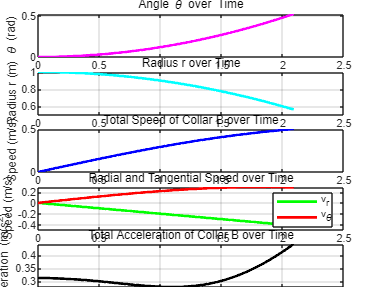

% 각도 및 거리 수식
theta_coeff = 0.12;
r_coeff = 0.1;

% 회전 각도 및 시간 계산
theta_target = pi/6; % 30 degrees in radians
t_target = sqrt(theta_target / theta_coeff); % t when theta = 30 degrees

% 시간 벡터 생성
t = linspace(0, t_target, 500);

% 각도 및 반경 계산
theta = theta_coeff * t.^2;
r = 1.0 - r_coeff * t.^2;

% 각속도 및 각가속도 계산
omega = 2 * theta_coeff * t; % d(theta)/dt
alpha = 2 * theta_coeff; % d^2(theta)/dt^2 is constant

% 반경 방향 속도 및 가속도
dr_dt = -2 * r_coeff * t;
d2r_dt2 = -2 * r_coeff;

% 속도 계산
vr = dr_dt; % 반경 방향 속도
vtheta = r .* omega; % 회전 방향 속도
v_B = sqrt(vr.^2 + vtheta.^2); % 전체 속도

% 가속도 계산
ar = d2r_dt2 - r .* omega.^2; % 반경 방향 가속도
atheta = r * alpha + 2 * dr_dt .* omega; % 회전 방향 가속도
a_B = sqrt(ar.^2 + atheta.^2); % 전체 가속도

% 동적 그래프 그리기
figure;
for i = 1:length(t)
    clf; % 기존 플롯 지우기
    
    subplot('Position', [0.1 0.8 0.8 0.15]); % [left bottom width height]
    plot(t(1:i), theta(1:i), 'm', 'LineWidth', 2);
    xlabel('Time (s)');
    ylabel('\theta (rad)');
    title('Angle \theta over Time');
    grid on;
    
    subplot('Position', [0.1 0.6 0.8 0.15]);
    plot(t(1:i), r(1:i), 'c', 'LineWidth', 2);
    xlabel('Time (s)');
    ylabel('Radius r (m)');
    title('Radius r over Time');
    grid on;
    
    subplot('Position', [0.1 0.4 0.8 0.15]);
    plot(t(1:i), v_B(1:i), 'b', 'LineWidth', 2);
    xlabel('Time (s)');
    ylabel('Speed (m/s)');
    title('Total Speed of Collar B over Time');
    grid on;
    
    subplot('Position', [0.1 0.2 0.8 0.15]);
    plot(t(1:i), vr(1:i), 'g', 'LineWidth', 2);
    hold on;
    plot(t(1:i), vtheta(1:i), 'r', 'LineWidth', 2);
    xlabel('Time (s)');
    ylabel('Speed (m/s)');
    legend('v_r', 'v_\theta');
    title('Radial and Tangential Speed over Time');
    grid on;
    
    subplot('Position', [0.1 0.0 0.8 0.15]);
    plot(t(1:i), a_B(1:i), 'k', 'LineWidth', 2);
    xlabel('Time (s)');
    ylabel('Acceleration (m/s^2)');
    title('Total Acceleration of Collar B over Time');
    grid on;
    
    drawnow; 
end

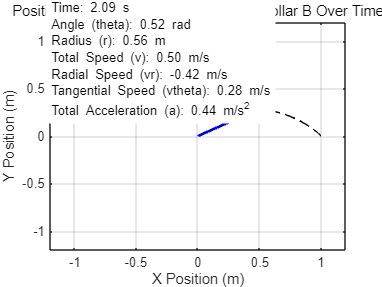

% 각도 및 거리 수식
theta_coeff = 0.12;
r_coeff = 0.1;

% 회전 각도 및 시간 계산
theta_target = pi/6; % 30 degrees in radians
t_target = sqrt(theta_target / theta_coeff); % t when theta = 30 degrees

% 시간 벡터 생성
t = linspace(0, t_target, 500);

% 각도 및 반경 계산
theta = theta_coeff * t.^2;
r = 1.0 - r_coeff * t.^2;

% 직교 좌표로 변환
x = r .* cos(theta);
y = r .* sin(theta);

% 각속도 및 각가속도 계산
omega = 2 * theta_coeff * t; % d(theta)/dt
alpha = 2 * theta_coeff; % d^2(theta)/dt^2 is constant

% 반경 방향 속도 및 가속도
dr_dt = -2 * r_coeff * t;
d2r_dt2 = -2 * r_coeff;

% 속도 계산
vr = dr_dt;
vtheta = r .* omega;
v_B = sqrt(vr.^2 + vtheta.^2); % 전체 속도

% 가속도 계산
ar = d2r_dt2 - r .* omega.^2; % 반경 방향 가속도
atheta = r * alpha + 2 * dr_dt .* omega; % 회전 방향 가속도
a_B = sqrt(ar.^2 + atheta.^2); % 전체 가속도

% 2D 동적 그래프 그리기
figure;
hold on;
axis equal;
xlim([-1.2, 1.2]);
ylim([-1.2, 1.2]);
xlabel('X Position (m)');
ylabel('Y Position (m)');
title('Position, Velocity, and Acceleration of Collar B Over Time');

% 동적 그래프
for i = 1:length(t)
    clf; % 기존 플롯 지우기
    
    % 막대 OA 그리기
    plot([0, x(i)], [0, y(i)], 'b', 'LineWidth', 2);
    hold on;
    
    % 칼라 B 위치 그리기
    plot(x(i), y(i), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
    
    % 궤적 그리기
    plot(x(1:i), y(1:i), 'k--');
    
    % 정보 표시
    info_text = {
        sprintf('Time: %.2f s', t(i)),
        sprintf('Angle (theta): %.2f rad', theta(i)),
        sprintf('Radius (r): %.2f m', r(i)),
        sprintf('Total Speed (v): %.2f m/s', v_B(i)),
        sprintf('Radial Speed (vr): %.2f m/s', vr(i)),
        sprintf('Tangential Speed (vtheta): %.2f m/s', vtheta(i)),
        sprintf('Total Acceleration (a): %.2f m/s^2', a_B(i))
    };
    
    % 텍스트 표시 (그래프 위쪽에 위치하도록 조정)
    text(-1.2, 0.8, info_text, 'FontSize', 10, 'BackgroundColor', 'w');
    
    xlim([-1.2, 1.2]);
    ylim([-1.2, 1.2]);
    grid on;
    xlabel('X Position (m)');
    ylabel('Y Position (m)');
    title('Position, Velocity, and Acceleration of Collar B Over Time');
    
    drawnow; % 업데이트된 플롯 그리기
end
hold off;

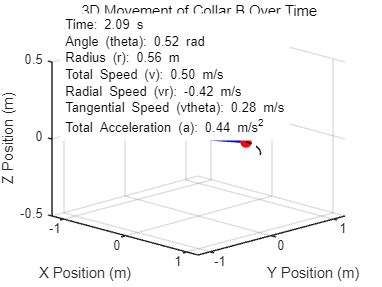

% 각도 및 거리 수식
theta_coeff = 0.12;
r_coeff = 0.1;

% 회전 각도 및 시간 계산
theta_target = pi/6; % 30 degrees in radians
t_target = sqrt(theta_target / theta_coeff); % t when theta = 30 degrees

% 시간 벡터 생성
t = linspace(0, t_target, 500);

% 각도 및 반경 계산
theta = theta_coeff * t.^2;
r = 1.0 - r_coeff * t.^2;

% 직교 좌표로 변환 (3D 표현을 위해 z 좌표를 0으로 설정)
x = r .* cos(theta);
y = r .* sin(theta);
z = zeros(size(t)); % z 값은 0으로 고정 (2D 평면을 3D 공간에 표시)

% 각속도 및 각가속도 계산
omega = 2 * theta_coeff * t; % d(theta)/dt
alpha = 2 * theta_coeff; % d^2(theta)/dt^2 is constant

% 반경 방향 속도 및 가속도
dr_dt = -2 * r_coeff * t;
d2r_dt2 = -2 * r_coeff;

% 속도 계산
vr = dr_dt;
vtheta = r .* omega;
v_B = sqrt(vr.^2 + vtheta.^2); % 전체 속도

% 가속도 계산
ar = d2r_dt2 - r .* omega.^2; % 반경 방향 가속도
atheta = r * alpha + 2 * dr_dt .* omega; % 회전 방향 가속도
a_B = sqrt(ar.^2 + atheta.^2); % 전체 가속도

% 3D 동적 그래프 그리기
figure;
hold on;
axis equal;
xlim([-1.2, 1.2]);
ylim([-1.2, 1.2]);
zlim([-0.5, 0.5]); % z축 범위 설정
xlabel('X Position (m)');
ylabel('Y Position (m)');
zlabel('Z Position (m)');
title('3D Movement of Collar B Over Time');

% 동적 그래프
for i = 1:length(t)
    clf; % 기존 플롯 지우기
    
    % 막대 OA 그리기
    plot3([0, x(i)], [0, y(i)], [0, z(i)], 'b', 'LineWidth', 2);
    hold on;
    
    % 칼라 B 위치 그리기
    plot3(x(i), y(i), z(i), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
    
    % 궤적 그리기
    plot3(x(1:i), y(1:i), z(1:i), 'k--');
    
    % 정보 표시
    info_text = {
        sprintf('Time: %.2f s', t(i)),
        sprintf('Angle (theta): %.2f rad', theta(i)),
        sprintf('Radius (r): %.2f m', r(i)),
        sprintf('Total Speed (v): %.2f m/s', v_B(i)),
        sprintf('Radial Speed (vr): %.2f m/s', vr(i)),
        sprintf('Tangential Speed (vtheta): %.2f m/s', vtheta(i)),
        sprintf('Total Acceleration (a): %.2f m/s^2', a_B(i))
    };
    
    % 텍스트 표시 (3D 공간에서 위치 조정)
    text(-1.1, -1.1, 0.4, info_text, 'FontSize', 10, 'BackgroundColor', 'w');
    
    xlim([-1.2, 1.2]);
    ylim([-1.2, 1.2]);
    zlim([-0.5, 0.5]);
    grid on;
    xlabel('X Position (m)');
    ylabel('Y Position (m)');
    zlabel('Z Position (m)');
    title('3D Movement of Collar B Over Time');
    
    view(45, 20); % 3D 보기 각도 설정
    drawnow; % 업데이트된 플롯 그리기
end
hold off;

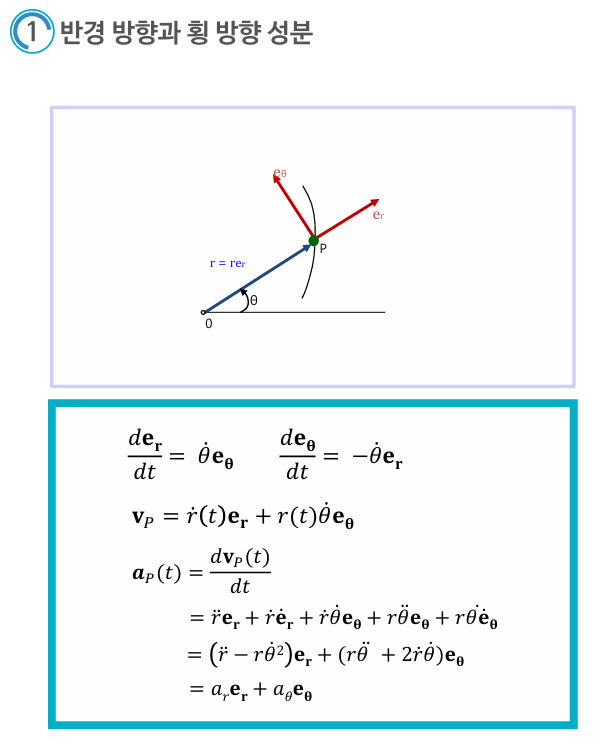

**1. 단위 벡터의 변화**

- 반경 방향 단위 벡터 $(e_r)$와 회전 방향 단위 벡터 ($e_\theta$)는 시간에 따라 변합니다. 이 변화를 수식으로 표현하면 다음과 같습니다: 


$$\frac{de_r}{dt} = \dot{\theta} e_\theta$$


$\frac{de_\theta}{dt} = -\dot{\theta} e_r$�

- $\dot{\theta}$는 각속도입니다.

- $e_r$의 변화는 $e_\theta$ 방향으로, $e_\theta$의 변화는 $e_r$의 반대 방향으로 이루어집니다.

**2. 속도 벡터 **$\mathbf{v_p}(t)$

- 물체의 속도 벡터는 반경 방향과 회전 방향의 합으로 표현됩니다: 

$\mathbf{v_p}(t) = \dot{r}(t) e_r + r(t) \dot{\theta} e_\theta$�

- $\dot{r}(t)$: 반경 방향 속도

- $r(t) \dot{\theta}$: 회전 방향 속도

**3. 가속도 벡터 **$\mathbf{a_p}(t)\$

- 가속도는 속도를 시간에 대해 미분하여 얻습니다: 


$$\mathbf{a_p}(t) = \frac{d\mathbf{v_p}(t)}{dt}$$



$$\mathbf{a_p}(t) = \frac{d}{dt}[\dot{r}(t) e_r + r(t) \dot{\theta} e_\theta]$$


- 곱의 미분 법칙을 적용하여 각 항을 미분합니다:

$\dot{r}(t) e_r$�의 미분:$\frac{d}{dt}[\dot{r}(t) e_r] = \ddot{r}(t) e_r + \dot{r}(t) \frac{de_r}{dt}$��

$\frac{de_r}{dt} = \dot{\theta} e_\theta$�

이므로,

$\frac{d}{dt}[\dot{r}(t) e_r] = \ddot{r}(t) e_r + \dot{r}(t) \dot{\theta} e_\theta$�

- $r(t) \dot{\theta} e_\theta$�의 미분:

$\frac{d}{dt}[r(t) \dot{\theta} e_\theta] = \frac{dr(t)}{dt} \dot{\theta} e_\theta + r(t) \ddot{\theta} e_\theta + r(t) \dot{\theta} \frac{de_\theta}{dt}$��

$\frac{de_\theta}{dt} = -\dot{\theta} e_r$�

이므로,

$\frac{d}{dt}[r(t) \dot{\theta} e_\theta] = \dot{r}(t) \dot{\theta} e_\theta + r(t) \ddot{\theta} e_\theta - r(t) \dot{\theta}^2 e_r$�

**4. 가속도 벡터의 최종 표현**

- 위의 두 항을 모두 합쳐서 가속도 벡터를 완성합니다: 


$$\mathbf{a_p}(t) = \ddot{r}(t) e_r + \dot{r}(t) \dot{\theta} e_\theta + \dot{r}(t) \dot{\theta} e_\theta + r(t) \ddot{\theta} e_\theta - r(t) \dot{\theta}^2 e_r$$


정리하면,

$\mathbf{a_p}(t) = (\ddot{r}(t) - r(t) \dot{\theta}^2) e_r + (r(t) \ddot{\theta} + 2\dot{r}(t) \dot{\theta}) e_\theta$�

**5. 가속도의 구성 요소**

- **반경 방향 가속도 (**$a_r$**�****)**:


$$a_r = \ddot{r}(t) - r(t) \dot{\theta}^2$$


- $\ddot{r}(t)$: 반경 방향 가속도

- $-r(t) \dot{\theta}^2$: 원심 가속도

- **회전 방향 가속도 **$(a_\theta)$:


$$a_\theta = r(t) \ddot{\theta} + 2\dot{r}(t) \dot{\theta}$$


- $r(t) \ddot{\theta}$: 각가속도에 의한 가속도

- $2\dot{r}(t) \dot{\theta}$: 코리올리 가속도

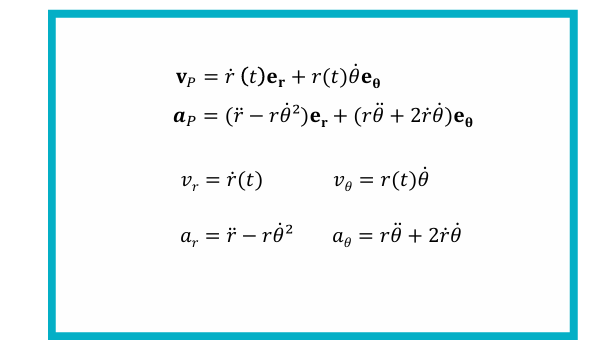

**속도 벡터 (**$\mathbf{v_p}$**�****)**

- 물체의 속도는 반경 방향 속도와 회전 방향 속도의 합으로 표현됩니다.

$\mathbf{v_p} = \dot{r}(t) e_r + r(t) \dot{\theta} e_\theta$�

- $\dot{r}(t)$: 반경 방향 속도

- $r(t) \dot{\theta}$: 회전 방향 속도

- $e_r, e_\theta$�: 각각 반경 및 회전 방향 단위 벡터

**가속도 벡터 (**$\mathbf{a_p}$**�****)**

- 속도 벡터를 시간에 대해 미분하여 가속도를 구합니다:


$$\mathbf{a_p} = \frac{d\mathbf{v_p}}{dt} = \ddot{r}(t) e_r + r(t) \ddot{\theta} e_\theta + \dot{r}(t) \dot{\theta} e_\theta + r(t) \dot{\theta}^2 (-e_r)$$


정리하면,


$$\mathbf{a_p} = (\ddot{r} - r \dot{\theta}^2) e_r + (r \ddot{\theta} + 2 \dot{r} \dot{\theta}) e_\theta$$


�**반경 방향 및 회전 방향 성분**

- **반경 방향 속도 및 가속도**:

- 반경 방향 속도 ($v_r$):


$$v_r = \dot{r}(t)$$


- 반경 방향 가속도 ($a_r$):


$$a_r = \ddot{r}(t) - r(t) \dot{\theta}^2$$


- 여기서 $r(t) \dot{\theta}^2$는 원심력에 의한 가속도를 나타냅니다.

- **회전 방향 속도 및 가속도**:

- 회전 방향 속도 ($v_\theta$�):


$$v_\theta = r(t) \dot{\theta}$$


- 회전 방향 가속도 ($a_\theta$):


$$a_\theta = r(t) \ddot{\theta} + 2 \dot{r}(t) \dot{\theta}$$


- $2 \dot{r}(t) \dot{\theta}$는 코리올리 가속도를 나타냅니다.

**요약**

- **속도**는 두 성분으로 나눌 수 있습니다:

- 반경 방향 속도 ($v_r = \dot{r}(t)$)

- 회전 방향 속도 ($v_\theta = r(t) \dot{\theta}$)

- **가속도**는 두 성분으로 나눌 수 있습니다:

- 반경 방향 가속도 $(a_r = \ddot{r}(t) - r(t) \dot{\theta}^2)$

- 회전 방향 가속도 $(a_\theta = r(t) \ddot{\theta} + 2 \dot{r}(t) \dot{\theta})$

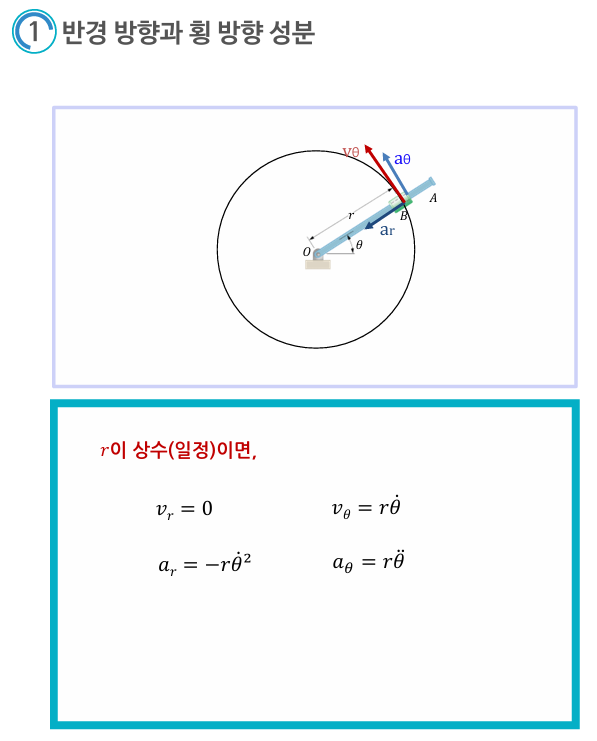

**상황 설명**

- **반경 **$r$**이 일정**:

- 물체가 원 궤도를 따라 움직이고 있으며, 반경 $r$은 변하지 않는 상수입니다.

- 이 경우, 반경 방향으로의 속도 성분은 0이 됩니다.

**속도 및 가속도 성분**

- **속도 성분**:

- **반경 방향 속도 (**$v_r$**)**: $v_r = \dot{r}(t) = 0$

- $r$이 상수이므로, 반경 방향으로의 속도 변화는 없습니다.

- **회전 방향 속도 (**$v_\theta$**�****)**:$v_\theta = r \dot{\theta}$

- 회전 방향 속도는 반경 $r$과 각속도 $\dot{\theta}$의 곱으로 나타납니다.

- 이는 물체가 일정한 반경을 따라 회전할 때의 접선 속도를 나타냅니다.

- **가속도 성분**:

- **반경 방향 가속도 (**$a_r$**)**: $a_r = -r \dot{\theta}^2$

- 반경 방향 가속도는 원심 가속도만 남습니다. 이 가속도는 원의 중심으로부터 바깥쪽을 향하며, 크기는 $r \dot{\theta}^2$에 비례합니다.

- **회전 방향 가속도 (**$a_\theta$**�****)**: $a_\theta = r \ddot{\theta}$

- 회전 방향 가속도는 반경과 각가속도 $\ddot{\theta}$의 곱으로 나타납니다.

- 이는 각가속도가 있을 때 접선 방향으로의 가속도를 나타냅니다.

**요약**

- **반경 **$r$**이 일정할 때**:

- **반경 방향 속도**는 0입니다. ($v_r = 0$)

- **회전 방향 속도**는 $v_\theta = r \dot{\theta}$로 나타납니다.

- **반경 방향 가속도**는 원심 가속도인 $a_r = -r \dot{\theta}^2$로 나타납니다.

- **회전 방향 가속도**는 $a_\theta = r \ddot{\theta}$로 나타납니다.

## **추가 상세 설명**

**1. 가속도 벡터의 정의**

- 가속도는 속도 벡터를 시간에 대해 미분하여 얻습니다:

$dt\mathbf{a_p}(t) = \frac{d\mathbf{v_p}(t)}{dt}$�

- 속도 벡터는 다음과 같이 표현됩니다:


$$\mathbf{v_p}(t) = \dot{r}(t) e_r + r(t) \dot{\theta} e_\theta$$


여기서,

- $\dot{r}(t)$: 반경 방향 속도

- $r(t) \dot{\theta}$: 회전 방향 속도

- $e_r, e_\theta$: 반경 및 회전 방향 단위 벡터

**2. 가속도 벡터의 미분**

- 가속도를 구하기 위해 속도 벡터를 시간에 대해 미분합니다: 


$$\mathbf{a_p}(t) = \frac{d}{dt}[\dot{r}(t) e_r + r(t) \dot{\theta} e_\theta]$$


**3. 미분 과정**

- 미분을 곱의 미분 법칙을 이용하여 각 항을 미분합니다:

- **첫 번째 항** $\dot{r}(t) e_r$�의 미분:

$\frac{d}{dt}[\dot{r}(t) e_r] = \ddot{r}(t) e_r + \dot{r}(t) \frac{de_r}{dt}$��

- 여기서 $\ddot{r}(t)$는 반경 방향의 가속도입니다.

- 단위 벡터 $e_r$의 시간에 대한 미분은 $\frac{de_r}{dt} = \dot{\theta} e_\theta$이므로,

$\frac{d}{dt}[\dot{r}(t) e_r] = \ddot{r}(t) e_r + \dot{r}(t) \dot{\theta} e_\theta$�

- **두 번째 항**$r(t) \dot{\theta} e_\theta$�의 미분:

$\frac{d}{dt}[r(t) \dot{\theta} e_\theta] = \frac{dr(t)}{dt} \dot{\theta} e_\theta + r(t) \frac{d\dot{\theta}}{dt} e_\theta + r(t) \dot{\theta} \frac{de_\theta}{dt}$��

- 여기서 $\frac{de_\theta}{dt} = -\dot{\theta} e_r$이므로,

$\frac{d}{dt}[r(t) \dot{\theta} e_\theta] = \dot{r}(t) \dot{\theta} e_\theta + r(t) \ddot{\theta} e_\theta - r(t) \dot{\theta}^2 e_r$�

**4. 가속도 벡터의 조합**

- 위에서 얻은 결과를 조합하여 가속도 벡터를 구성합니다: 

$\mathbf{a_p}(t) = \ddot{r}(t) e_r + \dot{r}(t) \dot{\theta} e_\theta + \dot{r}(t) \dot{\theta} e_\theta + r(t) \ddot{\theta} e_\theta - r(t) \dot{\theta}^2 e_r$�

**5. 정리**

- 이를 다시 정리하면 다음과 같습니다: 

$\mathbf{a_p}(t) = (\ddot{r} - r \dot{\theta}^2) e_r + (r \ddot{\theta} + 2 \dot{r} \dot{\theta}) e_\theta$�

여기서,

- **반경 방향 가속도** $(a_r): a_r = \ddot{r} - r \dot{\theta}^2$

- $\ddot{r}$: 반경 방향의 가속도

- $-r \dot{\theta}^2$: 원심 가속도

- **회전 방향 가속도** $(a_\theta)$: $a_\theta = r \ddot{\theta} + 2 \dot{r} \dot{\theta}$

- $r \ddot{\theta}$: 각가속도에 의한 가속도

- $2 \dot{r} \dot{\theta}$: 코리올리 가속도

�